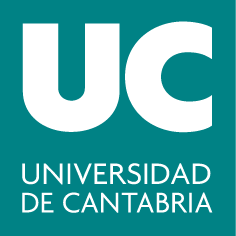

***Grados en Ingeniería Eléctrica y en  Ingeniería en Electrónica Industrial y Automática***

**Métodos Matemáticos para Ingeniería**

**Bloque II: Métodos Numéricos**

# **Tema 3: Aproximación de funciones por  polinomios. Optimización**

*Dpto. Matemática Aplicada y Ciencias de la Computación*

## 3.1. Interpolación y aproximación polinomial

Existen dos métodos generales para el ajuste de curvas:

#### Polinomio interpolador de Newton

**Problema de interpolación**: Determinar el polinomio único de $$n$$-ésimo grado que se ajuste a $$n + 1$$ puntos. Este polinomio proporciona una fórmula para calcular valores intermedios. Los puntos $$\{x_i\}_{i=0}^n$$ se llaman nodos de interpolación.

- [$n= 1$] Interpolación lineal:	        $$$f_1(x) = y_0 + \frac{y_1 - y_0}{x_1 - x_0}(x-x_0)  = b_0 + b_1(x-x_0)$$$

- [$n= 2$] Interpolación cuadrática:    $$$f_2(x) = b_0 + b_1 (x-x_0) + b_2 (x-x_0)(x-x_1)$$ $, donde

- 
$$$b_0 = y_0$$$


- 
$$ $b_1 = \frac{y_1 - y_0}{x_1 - x_0} = f[x_1, x_0]}$$$


- 
$$$b_2 = \frac{\frac{y_2 - y_1}{x_2 - x_1} - \frac{y_1 - y_0}{x_1 -
				x_0}}{x_2-x_0} =  f[x_2,x_1,x_0]} = \frac{f[x_2,x_1] - f[x_1,
			x_0]}{x_2-x_0}$$$


**Interpolación polinomial de Newton **de $$n$$-ésimo grado: 

	$$$f_n(x) = b_0 + b_1(x-x_0) + \ldots + b_n (x - x_0)\ldots (x-x_{n-1})$$$, donde

$$b_n = f[x_n, x_{n-1},\ldots, x_1, x_0]$ $- **diferencia dividida** de Newton

Las diferencias divididas de Newton satisfacen la siguiente relación recursiva	


$$f[x_n, x_{n-1},\ldots, x_1, x_0] = \frac{f[x_n,\ldots,x_1] - f[x_{n-1}, \ldots, x_0]}{x_n-x_0}$$


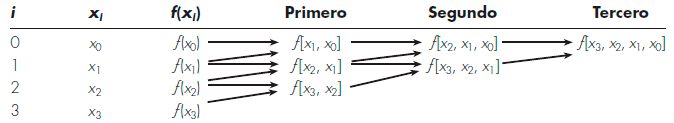

**Ejemplo: **Vamos a construir la tabla de diferencias divididas de la función $f(x) = \cos(x)$ para los puntos $(i,\, f(i))$, con $i = 0,1,2,3,4$.

1.  Definimos vector (columna) de los nodos $x_i = i$ y valores de la función $f$ en estos puntos $f[x_i]$:

clear all
xi = [0:4]';
b0 = cos(xi) % los coeficientes b0 

b0 =    1.000000000000000
   0.540302305868140
  -0.416146836547142
  -0.989992496600445
  -0.653643620863612


2. Calculamos la diferencias divididas usando la formula recursiva:

b1 = (b0(2:end) - b0(1:end-1))./ (xi(2:end) - xi(1:end-1)) 

b1 =   -0.459697694131860
  -0.956449142415282
  -0.573845660053303
   0.336348875736833


3. Repetimos los pasos para calcular $b_i, \;i = 2,3,4$:

b2 = (b1(2:end) - b1(1:end-1))./ (xi(3:end) - xi(1:end-2)) 

b2 =   -0.248375724141711
   0.191301741180990
   0.455097267895068


b3 = (b2(2:end) - b2(1:end-1))./ (xi(4:end) - xi(1:end-3)) 

b3 =    0.146559155107567
   0.087931842238026


b4 = (b3(2:end) - b3(1:end-1))./ (xi(5:end) - xi(1:end-4)) 

b4 =   -0.014656828217385


4. Ponemos todos los datos en una tabla para una mejor comprensión, sustituyendo los elementos ausentes por cero:

Tabla = [xi, b0, [b1; 0], [b2; 0; 0], [b3; 0; 0;0], [b4; 0; 0; 0; 0]]

Tabla =                    0   1.000000000000000  -0.459697694131860  -0.248375724141711   0.146559155107567  -0.014656828217385
   1.000000000000000   0.540302305868140  -0.956449142415282   0.191301741180990   0.087931842238026                   0
   2.000000000000000  -0.416146836547142  -0.573845660053303   0.455097267895068                   0                   0
   3.000000000000000  -0.989992496600445   0.336348875736833                   0                   0                   0
   4.000000000000000  -0.653643620863612                   0                   0                   0                   0


**Ejercicio:** Utiliza bucles para el cálculo eficiente de las diferencias divididas. El resultado debe ser el mismo.

Apartir de la tabla obtenida es muy facil escribir los polinomios interpoladores de Newton:

% definimos los coeficientes: 
b = Tabla(1,2:end) 

b =    1.000000000000000  -0.459697694131860  -0.248375724141711   0.146559155107567  -0.014656828217385


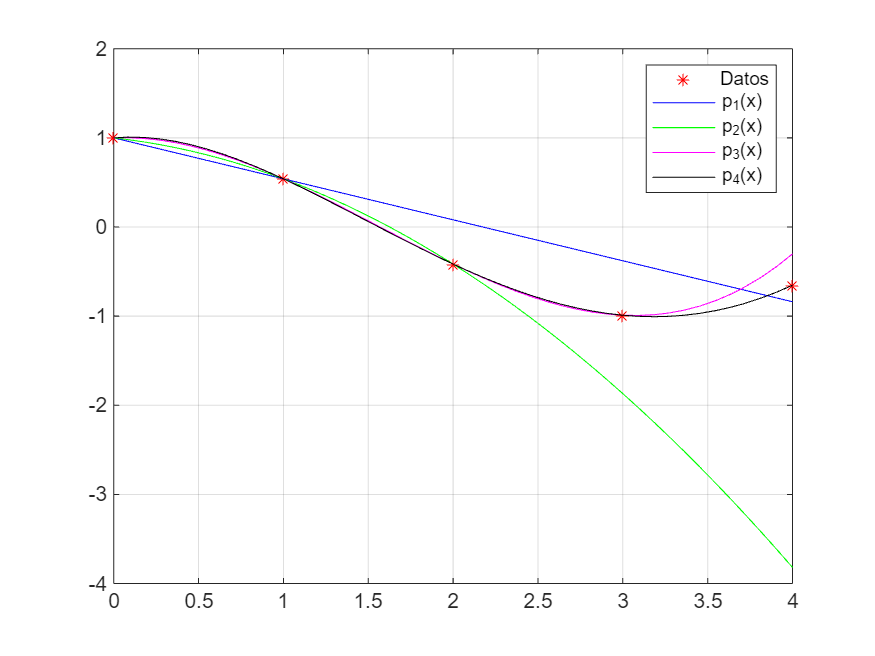

p1 = @(x)b(1) + b(2)*(x-xi(1));
p2 = @(x) b(1) + b(2)*(x-xi(1)) + b(3)*(x-xi(1)).*(x-xi(2));
p3 = @(x) b(1) + b(2)*(x-xi(1)) + b(3)*(x-xi(1)).*(x-xi(2)) + b(4)*(x-xi(1)).*(x-xi(2)).*(x-xi(3));
p4 = @(x) b(1) + b(2)*(x-xi(1)) + b(3)*(x-xi(1)).*(x-xi(2)) + b(4)*(x-xi(1)).*(x-xi(2)).*(x-xi(3)) + b(5)*(x-xi(1)).*(x-xi(2)).*(x-xi(3)).*(x-xi(4));
plot(xi,b0,'r*') % los puntos
hold on
fplot(p1,[xi(1), xi(end)],'b-')
fplot(p2,[xi(1), xi(end)],'g-')
fplot(p3,[xi(1), xi(end)],'m-')
fplot(p4,[xi(1), xi(end)],'k-')
grid on
legend ('Datos','p_1(x)', 'p_2(x)','p_3(x)','p_4(x)')
hold off

Las diferencias divididas en MATLAB:

Las ventajas de la interpolación de Newton:

1. **Fácil de actualizar**: Si se añade un nuevo punto de interpolación, el polinomio de Newton puede ser actualizado sin necesidad de recalcular completamente los coeficientes.

2. **Forma recursiva**: La fórmula de diferencias divididas de Newton permite una construcción recursiva del polinomio, lo que facilita su cálculo y comprensión. 

3. **Flexibilidad en los nodos**: No requiere que los nodos de interpolación sean equidistantes.

**Ejercicio:** Para el ejemplo anterior, construir el polinomio interpolador de Newton que pasa por los puntos $(x_i, y_i), \; i = 0,1,\ldots,4.$ En concreto, el vector de coeficientes del polinomio en potencias decrecientes de $x$.

% escribe el código aquí





Una posible implementación del método de Newton:

#### Interpolación de Lagrange

El polinomio de interpolación de Lagrange es simplemente una re-formulación del polinomio de Newton que evita el cálculo de las diferencias divididas.

Dados $$n + 1$$ puntos distintos$ $\{x_0, x_1,\ldots, x_n \}$$ del intervalo $$[a;
	b]$$ y una 	función $$f : [a; b] \rightarrow \mathbb{R}$$, se dice que un polinomio $$p$ $es el **polinomio de interpolación de Lagrange** de la función $$f$ $en los nodos citados si $$p$$ es de grado  $$ \leq n$$ y $$p(x_i) = f(x_i) = y_i$$ para cada $$0 \leq i \leq n$$.

	
$$p_n (x) = \sum_{i=0}^n L_i(x)y_i, \quad L_i(x) = \prod_{j=0, \; j\neq i}^n
	\frac{x-x_j}{x_i - x_j}$$$$


A los polinomios $$L_i$ $se les llama **polinomios básicos de Lagrange.**

1. [$$n=1$$] Interpolación lineal: $
		
		$$p_1 (x)= \frac{x-x_1}{x_0 - x_1}y_0 + \frac{x-x_0}{x_1 - x_0}y_1 $$$

2. [$n=2$] Interpolación cuadrática: $$$p_2(x) = \frac{(x-x_1)(x-x_2)}{(x_0 - x_1)(x_0 - x_2)}y_0 +
		\frac{(x-x_0)(x-x_2)}{(x_1 - x_0)(x_1 - x_2)}y_1+ \frac{(x-x_0)(x-x_1)}{(x_2
			- x_0)(x_2 - x_1)}y_2$$$

**Ejercicio: **Verifica que las fórmulas de interpolación lineal en las formas de Lagrange y Newton son equivalentes.

En muchos casos, es más útil conocer los coeficientes del polinomio interpolador en lugar de solo los valores en puntos específicos, como se ilustra en la interpolación de Newton.  

**Ejemplo:** Determinamos los coeficientes del polinomio de Lagrange para aproximar la función $f(x) = \cos(x)$ utilizando los nodos $(i,\, f(i))$,  $i = 0,1,2,3,4$.

1. Definimos los datos:

clear all
x = 0:4;    % vector-fila
y = cos(x); 

2. Calculamos los polinomios básicos de Lagrange:

w = length(x); % Número de nodos de interpolación
n = w - 1;     % Grado del polinomio interpolador
L = zeros(w, w);

% Calcular los polinomios básicos de Lagrange L_k(x)
for k = 1:n+1
    V = 1;
    for j = 1:n+1
        if k ~= j
            % Multiplicar por el factor (x - x(j)) y dividir por (x(k) - x(j))
            V = conv(V, poly(x(j))) / (x(k) - x(j));
        end
    end
    L(k, :) = V;
end
L

L =    0.041666666666667  -0.416666666666667   1.458333333333333  -2.083333333333333   1.000000000000000
  -0.166666666666667   1.500000000000000  -4.333333333333333   4.000000000000000                   0
   0.250000000000000  -2.000000000000000   4.750000000000000  -3.000000000000000                   0
  -0.166666666666667   1.166666666666667  -2.333333333333333   1.333333333333333                   0
   0.041666666666667  -0.250000000000000   0.458333333333333  -0.250000000000000                   0


3. Calcular el polinomio interpolador de Lagrange como una combinación lineal de los polinomios básicos, ponderados por los valores y:

   p = y * L

p =   -0.014656828217385   0.234500124411878  -0.849278299855648   0.169737309529296   1.000000000000000


4. Representamos el polinomio:

f1 = @(x) polyval(p,x);
plot(x,y,'r*') % los puntos
hold on
fplot(f1,[x(1), x(end)],'b-')
grid on
legend ('Datos','p_4(x)')
hold off

Función  que calcula los coeficientes del polinomio interpolador de Lagrange:

**Errores de la interpolación**

El error de truncamiento en la serie de Taylor:


$$$$R_n = \frac{|f^{(n+1)}(\xi)|}{(n+1)!}(x_{i+1} - x_{i})^n$$$$


Para un polinomio de interpolación de$ $n$$-ésimo grado:


$$$$R_n = \frac{|f^{(n+1)}(\xi)|}{(n+1)!}(x - x_0)(x-x_1)\ldots (x - x_n)$$$$


Supongamos que la función $$f$$ es $$n + 1$$ veces derivable en el intervalo $$[a;
b]$$  y que $$f^{(n+1)}$$ es una función continua, entonces una cota del error de interpolación de Lagrange viene dada por la expresión


$$$$|f(x)-f_n(x)| \leq \max_{\xi \in [a;b]} |f^{(n+1)}(\xi)| \frac{\left|
	\prod_{i=0}^n (x-x_i)\right|}{(n+1)!}$$$$


A la vista de la fórmula del error dada por el teorema anterior, es natural plantearse la elección de los nodos$ $\{x_i\}_{i=0}^n$$ de forma que la cantidad $$$\max_{x \in[a;b]}\left| \prod_{i=0}^n (x-x_i)\right| \rightarrow \min$$$

Esto se consigue tomando los llamados **nodos de Chebyshev**:

	
$$$$x_i = \frac{a+b}{2} + \frac{b-a}{2} \cos \frac{(2i+1)\pi}{2(n+1)}, \quad 0
	\leq i \leq n$$$$


Con esta elección de los nodos se tiene $$\max_{x \in[a;b]}\left| \prod_{i=0}^n (x-x_i)\right| =
\frac{(b-a)^{n+1}}{2^{2n+1}}$.$

**Ejercicio:** Implementa el código para calcular $n$ ($n= 1, 2,...$) nodos de Chebyshev en el intervalo $[0,\,1]$ en el orden ascedente.

clear all
a = 0;
b = 1;
n = 5;

% escribe  el código aquí





Para comprobar los resultados:

x2 = chebyshev(a,b,n)

x2 =     0.0245    0.2061    0.5000    0.7939    0.9755


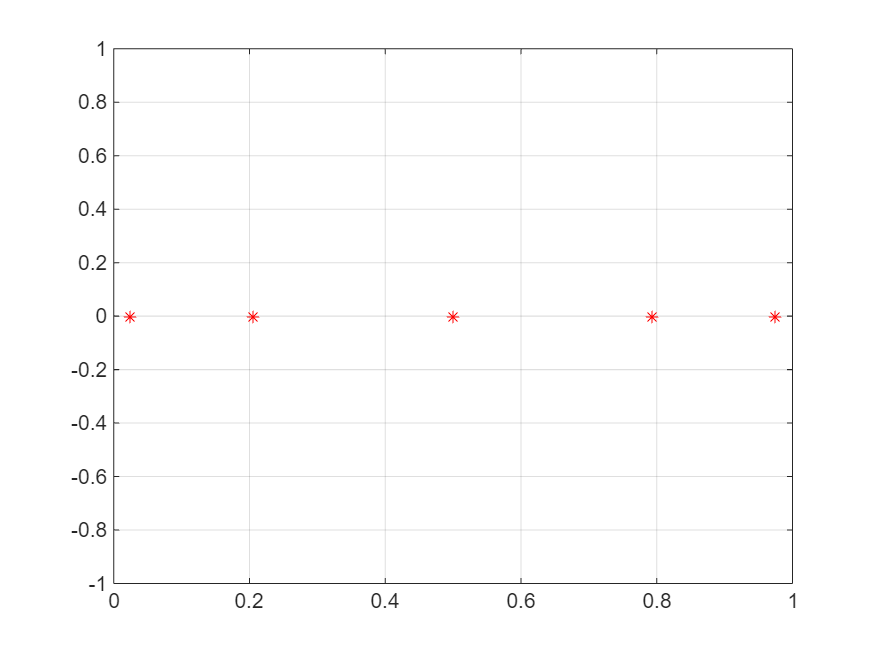

plot(x2,zeros(1,n),'r*')
grid on

#### Interpolación polinomial a trozos

-  Un procedimiento alternativo consiste en colocar polinomios de grado inferior en subconjuntos de los datos. Tales polinomios conectores se denominan **trazadores** o **splines**.

-  Las curvas de tercer grado empleadas para unir cada par de datos se llaman trazadores cúbicos. Esas funciones se pueden construir de tal forma que las conexiones entre ecuaciones cúbicas adyacentes resulten visualmente suaves.

El objetivo en los trazadores cúbicos es obtener un polinomio de tercer grado para cada intervalo entre los nodos:


$$$$S_i(x) = a_i + b_i (x-x_i) + c_i (x-x_i)^2 + d_i (x-x_i)^3$$$$


Longitud del intervalo $$i$$ es  $$h_i = x_{i+1}-x_i$$.

$$n+1$$ datos, $$n$$ intervalos $ \to 4n $ incógnitas $$\rightarrow$ $4n$$ condiciones:

- Los valores de la función deben ser iguales en los nodos interiores ($$2n - 2$$ condiciones):


$$$S_i(x_i) = f_i: \qquad \qquad a_i = f_i, \quad i = 1, \ldots, n$$$



$$$S_i(x_{i+1}) = f_{i+1}: \qquad  a_i + b_i h_i + c_i h_i^2 + d_i h_i^3 =
		f_{i+1}, \quad i = 1, \ldots, n$$$


- La primera y última función deben pasar a través de los puntos extremos (2 condiciones)

- Las primeras derivadas en los nodos interiores deben ser iguales ($n-1$ condiciones)


$$$S_i'(x_{i+1}) = S_{i+1}'(x_{i+1}): \quad b_i + 2c_ih_i + 3d_i h_i^2 = b_{i+1},
		\quad i = 1,\ldots, n-1$$$


- Las segundas derivadas en los nodos interiores deben ser iguales ($n-1$ condiciones)


$$	$S_i''(x_{i+1}) = S_{i+1}''(x_{i+1}): \quad 2c_i + 6d_ih_i = 2c_{i+1} \quad i =
		1,\ldots, n-1$$$


- Las segundas derivadas en los nodos extremos son cero  (2 condiciones)


$$$S_1''(x_1) = 0 : \quad 2c_1 = 0; \qquad S_{n}''(x_{n+1}) = 0 : \quad 2c_{n} + 6d_{n} h_{n} = 0$$$
 

Así, $ $a_i$$ son conocidos: $$ a_i = f_i$$; despejamos  $$b_{i} = \frac{f_{i+1}-f_{i}}{h_i} - \frac{2}{3} c_i h_i -
	\frac{1}{3}c_{i+1}h_i$$,       $$d_i = \frac{c_{i+1} - c_i}{2h_i}$$.

Se obtiene el siguiente sistema tridiagonal para resolver:


$$$$h_{i-1} c_{i-1} + 2(h_{i-1}+h_i)c_i + h_{i} c_{i+1} = 6 \left(
\frac{f_{i+1}-f_i}{h_{i} }  - \frac{f_{i}-f_{i-1}}{h_{i-1} }\right)$$$$


El comando `spline` en MATLAB ajusta un polinomio cúbico a trozos a un conjunto de puntos de datos.

- x: Vector de coordenadas $\( x \)$ de los puntos de datos.

- y: Vector de coordenadas $\( y \)$ de los puntos de datos.

- pp: Estructura de tipo ``pp`` (piecewise polynomial) que contiene la representación del polinomio cúbico por tramos.

- xq: Vector de puntos en los que se desea evaluar el polinomio interpolante.

- yq: Devuelve los valores interpolados en los puntos especificados por xq.

**Ejemplo:** 

clear all
x = linspace(0,4,10);
y = 1./cos(x);

% Calcular el polinomio de interpolación cúbica
pp = spline(x, y)
% Evaluar el polinomio en puntos nuevos
xq = linspace(0, 4, 100);
yq = ppval(pp, xq); % OJO! no es 'polyval'
% Graficar los puntos originales y la interpolación
plot(x, y, 'r*', xq, yq, 'b-');
grid on
legend('Datos', 'Trazador cúbico');

#### Regresión en mínimos cuadrados

Cuando los datos tienen errores sustanciales, la interpolación polinomial es inapropiada y puede dar resultados poco satisfactorios cuando se utiliza para predecir valores intermedios. Una estrategia más apropiada en tales casos consiste en obtener una función de aproximación que se ajuste a la forma o a la tendencia general de los datos, sin coincidir necesariamente en todos los puntos.

Se debe encontrar algún criterio para establecer una base para el ajuste. Una forma de hacerlo es obtener una curva que minimice 	la discrepancia entre los puntos y la curva. Una técnica para lograr tal objetivo, llamada **regresión por mínimos cuadrados**.

Dados $$n + 1$ $ puntos distintos $$\{x_0, x_1, \ldots, x_n\}$$ del intervalo $[a,b]$, una función $$f : [a; b]\rightarrow \mathbb{R}$$, el problema de mínimos cuadrados consiste en resolver

	
$$
	$$\sum_{j=0}^n \left(f(x_j) - p(x_j)\right)^2 \rightarrow \min$$$$


**Regresión lineal**: ajustar una línea recta a un conjunto de observaciones definidas por puntos:$ $(x_1, y_1)$, $(x_2, y_2)$, $\ldots$, $(x_n, y_n)$$.

Ecuación de una recta: $$y = a_0 + a_1x + e$$,  donde $$e$ $es el error o residuo: $e = y - (a_0 + a_1x)$.

Criterio para un "mejor" ajuste: 	$$S_r = \sum_{i=1}^n e_i^2 = \sum_{i=1}^n (y_i - a_0 - a_1x_i)^2 \rightarrow
	\min$$

Para determinar los valores de $$a_0$ y $a_1$, $S_r$$ se deriva con respecto a cada uno de los coeficientes:


$$$$\frac{\partial S_r}{\partial a_0} = -2 \sum (y_i-a_0 - a_1x_i),
\qquad\frac{\partial S_r}{\partial a_1} = -2 \sum (y_i-a_0 - a_1x_i)x_i$$$$


Al igualar estas derivadas a cero, se dará como resultado un $$S_r$$ mínimo:

$$$\begin{cases} \sum y_i - n a_0 - a_1\sum x_i
= 0
\\ \sum x_i y_i - a_0 \sum x_i - a_1 \sum x_i^2
= 0
\end{cases}$$$, de donde


$$
$$a_1 = \frac{n \sum x_i y_i -\sum x_i \sum y_i}{n \sum x_i^2 - \left(\sum x_i
	\right)^2}, \quad
a_0 = \frac{1}{n}\left(\sum y_i -a_1 \sum x_i \right)$$$$


**Ejemplo**: Ajuste a una línea recta los valores $$x$$ e $$y$$:

clear all
x = 1:7;
y = [0.5 2.5 2.0 4.0  3.5  6.0  5.5];
plot(x,y,'r*')
grid on

pp = struct with fields:
      form: 'pp'
    breaks: [0 0.444444444444444 0.888888888888889 1.333333333333333 1.777777777777778 2.222222222222222 2.666666666666667 3.111111111111111 3.555555555555555 4]
     coefs: [9×4 double]
    pieces: 9
     order: 4
       dim: 1


	Se calculan las siguientes cantidades:

n = length(x);
sx = sum(x);
sy = sum(y);
sxy = x*y';
sx2 = x*x';	

 $$n= 7$, $\sum x_i = 28$, $\sum y_i = 24$$, $$\sum x_i y_i= 119.5$, $\sum x_i^2 = 140$$

Entonces, 


$$$$\begin{cases} \sum y_i - n a_0 - a_1\sum x_i
= 0
\\ \sum x_i y_i - a_0 \sum x_i - a_1 \sum x_i^2
= 0
\end{cases}
\Rightarrow 
	\begin{cases} 24 -7 a_0 - 28a_1  = 0
	\\ 119.5 - 28 a_0  - 140a_1  = 0
	\end{cases}
\Rightarrow 
	\begin{cases} 7 a_0 + 28a_1  = -24 
	\\   28 a_0  +140a_1  = -119.5
	\end{cases}$$


Resolvemos este sistema:

A = [n sx; sx sx2]; % matríz del sistema
b = [sy; sxy];
a = A\b

Se obtienen los coeficientes: $	$a_1 = 0.8392857, \quad a_0 = 0.07142857$$. La recta de regresión será:


$$y =  0.8392857x +  0.07142857$$$


recta = @(x) a(2)*x+a(1);
hold on
fplot(recta,[x(1), x(end)],'b-')
legend('Datos', 'Regresión lineal')
hold off

**Regresión polinomial**

El procedimiento de mínimos cuadrados se puede extender fácilmente al ajuste de datos con un polinomio de grado superior. Por ejemplo, suponga que ajustamos un polinomio de segundo grado o cuadrático:


$$$$y = a_0 + a_1 x + a_2 x^2 +e $$$$


La suma de los cuadrados de los residuos es


$$$$S_r = \sum_{i=1}^n \left(y_i- a_0 - a_1 x_i - a_2 x_i^2\right)^2\to \min$$$$


La derivada de $$S_r$$ con respecto a cada uno de los coeficientes desconocidos del polinomio:


$$$$
\begin{cases}
\frac{\partial S_r }{\partial a_0} = -2 \sum \left(y_i - a_0 - a_1 x_i - a_2
x_i^2\right) 
\\
\frac{\partial S_r }{\partial a_1} = -2 \sum  \left[ \left(y_i - a_0 - a_1 x_i -
a_2 x_i^2\right)x_i\right]
\\
\frac{\partial S_r }{\partial a_2} = -2 \sum \left[ \left(y_i - a_0 - a_1 x_i -
a_2 x_i^2\right)x_i^2\right]
\end{cases}
$$$$


Estas ecuaciones se igualan a cero y se re-ordenan:


$$\begin{cases}
n a_0  +  \left(\sum x_i \right) a_1 +  
\left(\sum x_i^2 \right)a_2 =   \left(\sum y_i \right)
\\
\left(\sum x_i \right) a_0+ \left(\sum x_i^2
\right) a_1+  \left(\sum x_i^3 \right) a_2
=  \left(\sum x_i y_i \right)
\\
\left(\sum x_i^2 \right) a_0+ \left(\sum x_i^3
\right) a_1+ \left(\sum x_i^4 \right)a_2
= \left(\sum x_i^2 y_i \right)
\end{cases}
$$
$$


**Ejemplo**: Ajustamos a un polinomio de segundo grado los datos $$x$ e $y$$:

clear all
x = 0:5;
y = [2.1  7.7    13.6    27.2   40.9   61.1];
plot(x,y,'r*')
grid on

Calculamos los coeficientes del sistema:

m = 2; % grado del polinomio

Para simplificar los cálculos, evaluamos $\(x^0\), \(x^1\) y \(x^2\)$ en una sola línea:

x'.^[0:m] 

a =    0.071428571428571
   0.839285714285714


Si ahora sumamos los elementos en cada columna, obtenemos $n, \sum x,\sum x^2$, respectivamente:

A1 = sum(x'.^[0:m] )

Son los coeficientes de la primera ecuación. De manera similar, podemos calcular los coeficientes de la segunda y tercera ecuaciones:

A2 = sum(x'.^[1:m+1]);
A3 = sum(x'.^[2:m+2]);
A = [A1; A2; A3]

Se puede obtener el mismo resultado usando un bucle. Hazlo tú. 

% escribe aquí el código



Para calcular el vector $b$ hacemos lo mismo:

b = sum(y'.*(x'.^[0:m]))' 

Calculamos los coeficientes:

a = A\b


$$	$a_0 = 2.47857$, $a_1 = 2.35929$, $a_2 = 1.86071$$$


Para evaluar el polinomio podemos utilizar el comando `polyval.` Para ello, debemos invertir el orden de los coeficientes:

a = flipud(a)

Ahora podemos representar la curva:

recta = @(x) polyval(a,x);
hold on
fplot(recta,[x(1), x(end)],'b-')
legend('Datos', 'Regresión cuadrática')
hold off

ans =      1     0     0
     1     1     1
     1     2     4
     1     3     9
     1     4    16
     1     5    25


En el caso del polinomio de $m$-ésimo grado:


$$$$
\begin{cases}
(n)  a_0 & + & \left(\sum x_i \right) a_1 & + & 
\ldots &  \left(\sum x_i^{m} \right)a_m& = &  \left(\sum y_i
\right)
\\
\left(\sum x_i \right)  a_0 & + & \left(\sum x_i^2
\right)a_1& + & \ldots &  \left(\sum x_i^{m+1}
\right)a_m & = &  \left(\sum x_i y_i \right)
\\
\ldots &  & & & & & 
\\
\left(\sum x_i^{m} \right) a_0 & + & \left(\sum x_i^{m+1}
\right) a_1 & + & \ldots & \left(\sum x_i^{2m}
\right) a_m & = &  \left(\sum x_i^{m} y_i \right)
\end{cases}
$$$$


**Ejercicio**: Escribe un programa que calcule los coeficientes del polinomio de $m$-ésimo grado que se ajuste a los datos $(x_i, y_i)$). La función debe devolver un vector con los coeficientes del polinomio en orden descendente de potencias.

clear all
x = 0:5;

A1 =      6    15    55


y = [2.1  7.7    13.6    27.2   40.9   61.1];
plot(x,y,'r*')
grid on
m = 3; % grado del polinomio

A =      6    15    55
    15    55   225
    55   225   979


#### Interpolación y regresión con MATLAB

MATLAB proporciona diversas funciones para realizar interpolación, siendo las más comunes `interp1`, `spline` y `polyfit`.

- La función [`interp1`](https://es.mathworks.com/help/matlab/ref/interp1.html) en MATLAB se utiliza para realizar interpolación unidimensional en un conjunto de datos:

` -``x`: Vector de coordenadas x de los puntos de datos conocidos.

  - y: Vector de valores y correspondientes a las coordenadas x.

` -``xq`: Vector de puntos donde se desea realizar la interpolación.

` -``yq`: Valores interpolados en los puntos xq.

- El comando [`spline`](https://es.mathworks.com/help/matlab/ref/spline.html) en MATLAB ajusta un polinomio cúbico a trozos a un conjunto de puntos de datos.

- x: Vector de coordenadas $\( x \)$ de los puntos de datos.

- y: Vector de coordenadas $\( y \)$ de los puntos de datos.

- p: Estructura de tipo ``p`` (piecewise polynomial) que contiene la representación del polinomio cúbico por tramos.

- La función [`polyfit`](https://es.mathworks.com/help/matlab/ref/polyfit.html) en MATLAB se utiliza para realizar ajustes polinómicos a un conjunto de datos. 

- x: Vector de coordenadas $\( x \)$ de los puntos de datos.

- y: Vector de coordenadas $\( y \)$ de los puntos de datos.

- n: Grado del polinomio.

- p: Vector de coeficientes del polinomio de grado nnn en orden descendente de potencias.

La función `polyfit` calcula los coeficientes de un polinomio $p(x)$ de grado$n$ que minimiza el error cuadrático entre los valores del polinomio y los datos proporcionados. Los coeficientes se devuelven en un vector, comenzando con el coeficiente de la potencia más alta.

La función `polyfit` también se puede utilizar para resolver el problema de interpolación, ya que el polinomio de grado $n$ que se ajusta a $n+1$ puntos es único.

**Ejemplo: **

clear all
x = 0:5;
y = [2.1  7.7    13.6    27.2   40.9   61.1];
plot(x,y,'r*')
grid on
m = 5; % grado del polinomio

b = 1.0e+03 *

   0.152600000000000
   0.585600000000000
   2.488800000000000


p = polyfit(x,y,m);
recta = @(x) polyval(p,x);

a =    2.478571428571406
   2.359285714285740
   1.860714285714281


hold on
fplot(recta,[x(1), x(end)],'b-')
legend('Datos', 'Polinomio interpolador')

a =    1.860714285714281
   2.359285714285740
   2.478571428571406


hold off

## 3.2. Optimización numérica

Llamamos **optimización** al acto de obtener el mejor resultado posible dadas ciertas circunstancias. En matemáticas y ciencias aplicadas, la optimización implica encontrar el valor óptimo de una función en un dominio específico. Este valor puede ser un mínimo o un máximo, dependiendo del problema.

La localización de raíces (Tema 2) y la optimización están relacionadas en el sentido de que ambas involucran la búsqueda de un punto en una función:

- Localización de raíces: Consiste en encontrar los ceros de una función, es decir, los puntos donde la función se anula $( f(x) = 0)$.

- Optimización: Consiste en encontrar el mínimo o el máximo de una función, es decir, los puntos donde la función alcanza sus valores extremos.

#### Optimización unidimensional

	La función $$f(x)$$ es **unimodal** en el intervalo $$[a,b]$ $si existe el punto $$x^* \in [a,b]$$ tal que $$\forall x_1, x_2 \in [a,b], \; x_1 < x_2$$ se cumple 

- 
$$ $f(x_1) >f (x_2)$, si $x_2<x^*$,$$


- $$f(x_1) < f(x_2)$, si $x*<x_1<x_2$$.

La función se llama  unimodal  en un intervalo, si tiene sólo un extremo en este intervalo.

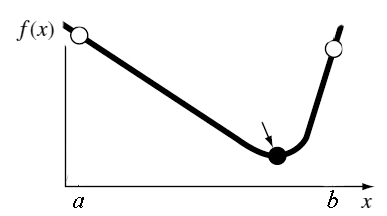

**Métodos de la optimización unidimensional**

- Métodos cerrados (métodos de eliminación de regiones):  Método de bisección (dicotomía), Método de la sección dorada, etc.

- Métodos indirectos: Método de Newton, Método de la secante

-  Métodos de aproximación polinomial

**Métodos cerrados**

Este tipo de métodos se centra en la búsqueda de soluciones óptimas mediante sucesivas reducciones del intervalo de estudio y la eliminación de subintervalos. Si la función es unimodal (tiene un único mínimo o máximo en el intervalo considerado), se puede definir un criterio para eliminar regiones donde el óptimo seguramente no se encuentra. Cuando el subintervalo “sobreviviente” tenga una longitud suficientemente pequeña, la búsqueda termina.

**Ventajas de los Métodos cerrados**

La gran ventaja de estos métodos de búsqueda es que solo requieren evaluaciones de la función y no necesitan ninguna hipótesis adicional acerca de la derivabilidad de la misma. Esto significa que se pueden aplicar a una amplia gama de funciones, incluidas aquellas que no son suaves o que no tienen derivadas continuas.

**Método de bisección (dicotomía)**

El método de dicotomía, también conocido como método de bisección, en el contexto de optimización, se utiliza para encontrar el mínimo o máximo de una función unimodal en un intervalo cerrado$ \([a, b]\)$. El método  se basa en reducir el intervalo de búsqueda en cada iteración, dividiéndolo en dos subintervalos y eliminando el subintervalo donde no puede estar el óptimo. El proceso se repite hasta que el intervalo sea suficientemente pequeño.

1.Definir el intervalo inicial $\([a, b]\)$ y una tolerancia $\(\epsilon\)$.

2. En cada iteración, evaluar la función en dos puntos, $\(x_1\) y \(x_2\)$, que están equidistantes del punto medio del intervalo $\([a, b]\)$:


$$    x_1 = \frac{a + b }{2}- \delta, \quad x_2 = \frac{a + b }{2}+ \delta$$


 donde $\(\delta\)$ es una pequeña constante positiva.

3. Reducir del Intervalo:

    - Si $\(f(x_1) < f(x_2)\)$, entonces el mínimo se encuentra en $\([a, x_2]\)$, y se actualiza $ \(b = x_2\)$.

    - Si $\(f(x_1) > f(x_2)\)$, entonces el mínimo se encuentra en $\([x_1, b]\)$, y se actualiza $\(a = x_1\)$.

4. Repetir el proceso hasta que la longitud del intervalo $\([a, b]\)$ sea menor que la tolerancia $\(\epsilon\)$.

**Ejemplo: **encontrar el mínimo de la función $\(f(x) = (x-2)^2 + 3\)$ en el intervalo $\([0, 3]\)$ con una tolerancia de $\(10^{-6}\)$.

1.Definir el intervalo inicial $\([a, b]\)$ y una tolerancia $\(\epsilon\)$.

clear all
close all
f = @(x) (x-2).^2+3;
a = 0; b = 3;
epsilon = 1e-6; 
delta = epsilon/2;
fplot(f,[a,b],'b-')
grid on

La función es unimodal en el itervalo $[a,b]$, entonces, se puede aplicar el método de bisección.

2. Definir dos puntos: $    x_1 = \frac{a + b }{2}- \delta, \quad x_2 = \frac{a + b }{2}+ \delta$

x1 = (a+b)/2-delta; x2 = (a+b)/2+delta;
f1 = f(x1); f2 = f(x2);
fprintf("f(%.4f) = %.4f,\tf(%.4f) = %.4f",x1,f1,x2,f2)

Entonces, en el punto $x = \frac{a+b}{2}$ la función decrece y el mínimo no puede estar en el subintervalo $[a,x_1].$ 

3. Reducir del Intervalo:

a = x1;

4. Repetir el proceso:

x1 = (a+b)/2-delta; x2 = (a+b)/2+delta;
f1 = f(x1); f2 = f(x2);
fprintf("f(%.4f) = %.4f,\tf(%.4f) = %.4f",x1,f1,x2,f2)

Entonces, en el punto $x = \frac{a+b}{2}$ la función crece y el mínimo no puede estar en el subintervalo $[x_2,b].$

b = x2;
x1 = (a+b)/2-delta; x2 = (a+b)/2+delta;
f1 = f(x1); f2 = f(x2);
fprintf("f(%.4f) = %.4f,\tf(%.4f) = %.4f",x1,f1,x2,f2)

... 

Escribimos el algoritmo completo:

clear all
close all
f = @(x) (x-2).^2+3;
a = 0; b = 3;
epsilon = 1e-6; 
delta = epsilon/2;

while (b - a) / 2 > epsilon
    x1 = (a + b) / 2 - delta;
    x2 = (a + b) / 2 + delta;
    f1 = f(x1);     f2 = f(x2);  
    % Comparar y actualizar el intervalo
    if f1 < f2
        b = x2;
    else
        a = x1;
    end
    l = b-a;
end
xmin = (a + b) / 2;
fmin = f(xmin);  
fplot(f,[a,b],'b-')
grid on
hold on
plot(xmin,fmin,'r*')

**Método de la sección dorada**

Este método es una mejora del método de dicotomía y se basa en la propiedad matemática de la proporción áurea. El método de la sección dorada divide el intervalo de búsqueda en segmentos que mantienen una proporción constante, llamada proporción áurea. Esta proporción es aproximadamente $\varphi=\frac{1+\sqrt{5}}{2}\approx1.618$.

Algoritmo:

1. Calcular la razón dorada: $$d = \frac{\sqrt{5}-1}{2}$$ y poner $$\tau = 1-d = \frac{3-\sqrt{5}}{2}$$

2. Elegir dos puntos interiores: $$x_1 = a + \tau(b-a)$$, $$x_2 = a+b-x_1$$

3. Evaluar la función $$f(x)$ $en estos dos puntos.

4. Comparar los valores $$f(x_1)$$ y $$f(x_2)$$:

	- Si$ $f(x_1) \leq f(x_2)$$, poner $$b= x_2$, $x_2 = x_1$, $x_1 = a+b-x_2$$;

	- Si $$f(x_1) > f(x_2)$$, poner $$a= x_1$, $x_1 = x_2$, $x_2 = a+b-x_1$$;

5. Calcular la longitud del intervalo: $$L = b-a$$.

6. Repetir el proceso hasta que $$L<\epsilon$$, 

7. $$x_{opt} = 0.5(a+b)$$;

**Ejercicio**: Dada la función $$f(x) = x^4 +2x^3+8x^2+5x$$, hallar el mínimo de $$f(x)$$ en el intervalo $$[-2, \, 1]$$ con $\epsilon = 10^{-6}$. ¿Cuántas iteraciones se necesitan?

clear all
close all
f = @(x)x.^4 +2*x.^3+8*x.^2+5*x;
a = -2; b = 1; tol = 1e-6;

% escribe el código aquí



**Métodos indirectos**

**Método de Newton** para $$f(x)= 0$$: $$x_{k+1} = x_k - \frac{f(x_k)}{f'(x_k)}$$

Punto crítico: $$f'(x) = 0$ \rightarrow$ Aplicar el método de Newton para la ecuación$ $f'(x) =0$$:


$$$$x_{k+1} = x_k - \frac{f'(x_k)}{f''(x_k)}$$$$


asegurando que para cada paso $$k$$, $$f(x_{k+1})<f(x_k).$$ 

**Ventajas:** converge cuadráticamente. Para una función cuadrática converge con una iteración.

Desventajas: se deben calcular las derivadas primeras y segundas. Si las derivadas	segundas son nulas el método converge lentamente. 

**Ejemplo:** Dada la función$ $f(x) = x^4 +2x^3+8x^2+5x$$, hallar el mínimo de $$f(x)$$ en el intervalo $$[-2, \, 1]$$.

clear all
close all
f = @(x) x.^4 +2*x.^3+8*x.^2+5*x;
df = @(x) 4*x.^3 + 6*x.^2 + 16*x+5;
d2f = @(x) 12*x.^2 + 12*x + 16;
a = -2; b = 1; tol = 1e-6;
fplot(f,[a,b],'b-')
grid on

Función es unimodal. Elegimos como la aproximación inicial el punto medio: $x_0 = \frac{a+b}{2}$

x = (a+b)/2;
for k = 1:100
    x1 = x;
    if abs(d2f(x))>eps
        x = x - df(x)/d2f(x);
    else
        disp('diverge!'); break;
    end
    if abs(df(x))<tol || abs(x-x1)<tol
        break;
    end
end
xmin = x;
fmin = f(xmin);
fprintf("x_min = %.4f, f_min = %.4f\n Iteraciones: %d",xmin,fmin,k)

**Optimization Toolbox**

[`fminbnd`](https://es.mathworks.com/help/matlab/ref/fminbnd.html)`: `Para funciones unidimensionales, MATLAB ofrece la función `fminbnd` para encontrar el mínimo de una función en un intervalo dado.

- **fun**: La función que se va a minimizar, definida como un handle de función.

- **x1, x2**: Los límites inferior y superior del intervalo de búsqueda.

- **options**: Una estructura de opciones para personalizar el comportamiento del algoritmo.

- **x**: El punto donde se alcanza el valor mínimo de la función.

- **fval**: El valor de la función en el punto mínimo.

- **exitflag**: Un indicador del estado de salida.

- **output**: Una estructura que contiene información sobre el proceso de optimización.

La función `fminbnd` permite ajustar varias opciones de optimización mediante la función `optimset`. Algunas opciones comunes incluyen:

- **TolX**: La tolerancia en el valor de xxx.

- **MaxIter**: El número máximo de iteraciones.

- **MaxFunEvals**: El número máximo de evaluaciones de la función.

clear all 
close all
f = @(x)x.^4 +2*x.^3+8*x.^2+5*x;
a = -2; b = 1;
options = optimset('TolX',1e-6)
[x,fval,exitflag,output] = fminbnd(f,a,b,options)

#### **Programación lineal**

Dado el problema:

	
$$$\min_x f^Tx$

	$Ax \leq b$, 
	
	$A_ex = b_e$,
	
	$a \leq x \leq  b$ $$


La función [`linprog`](https://es.mathworks.com/help/optim/ug/linprog.html) en MATLAB se utiliza para resolver problemas de programación lineal, donde el objetivo es minimizar una función lineal sujeta a restricciones lineales. Es ampliamente utilizada en optimización y en diversas aplicaciones industriales y científicas.

Argumentos de entrada: 

- `f`: Vector de coeficiente, especificado como un vector real o una matriz real.

- `A`: Restricciones de desigualdad lineales, especificadas como una matriz real.

- `b`: Restricciones de desigualdad lineales, especificadas como un vector real. 

- `Aeq`: Restricciones de igualdad lineales, especificadas como una matriz real. 

- `beq`: Restricciones de igualdad lineales, especificadas como un vector real.

- `lb`: Límites inferiores.

- `ub`: Límites superiores.

- `options`: Estructura de opciones como devuelta por `optimoptionsoptimset`.

**Ejemplo**: 	Un herrero con 80 kg de acero y 120 kg de aluminio quiere hacer bicicletas de paseo y de montaña que quiere vender, respectivamente a 250 y 450 euros cada una para sacar el máximo beneficio. Para la de paseo empleará 1 kg de acero y 3 kg de aluminio, y para la de montaña 2 kg de ambos metales. ¿Cuántas bicicletas de paseo y de montaña deberá fabricar para maximizar las utilidades?


$$$$\begin{cases}
	f(x,y)  =250x + 450y \rightarrow \max
	\\
	x+2y \leq 80\\
	3x+2y \leq 120\\
	x,y \geq 0
\end{cases}$$$$


linprog resuelve los problemas de minimización, por lo tanto cambiamos el signo en la función objetivo:

f = -[250 450];
A = [1 2; 3 2];
b = [80 120];
Aeq = []; beq=[];
lb = [0; 0;];
linprog(f,A,b,Aeq,beq,lb)

## Bibliografía

- [Chapra S.C.; Canale R. (2015) Métodos Numéricos para Ingenieros. Ed. McGRaw-Hill](https://catalogo.unican.es/cgi-bin/abnetopac?TITN=436963) (Capítulos 17-18, 13-16)

- [Mathews J.H., Fink K.D. (2000) Métodos Numéricos con MATLAB. Ed. Prentice Hall](https://catalogo.unican.es/cgi-bin/abnetopac?TITN=163396) (Capítulos 4,5 y 8)

Funciones auxiliares

1. Nodos de Chebyshev:

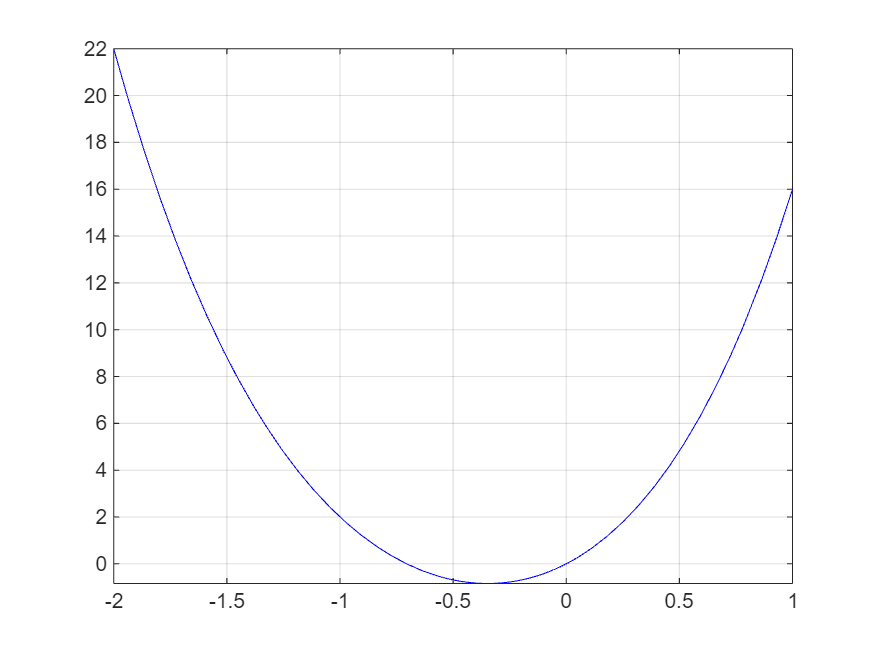

x_min = -0.3473, f_min = -0.8408
 Iteraciones: 3

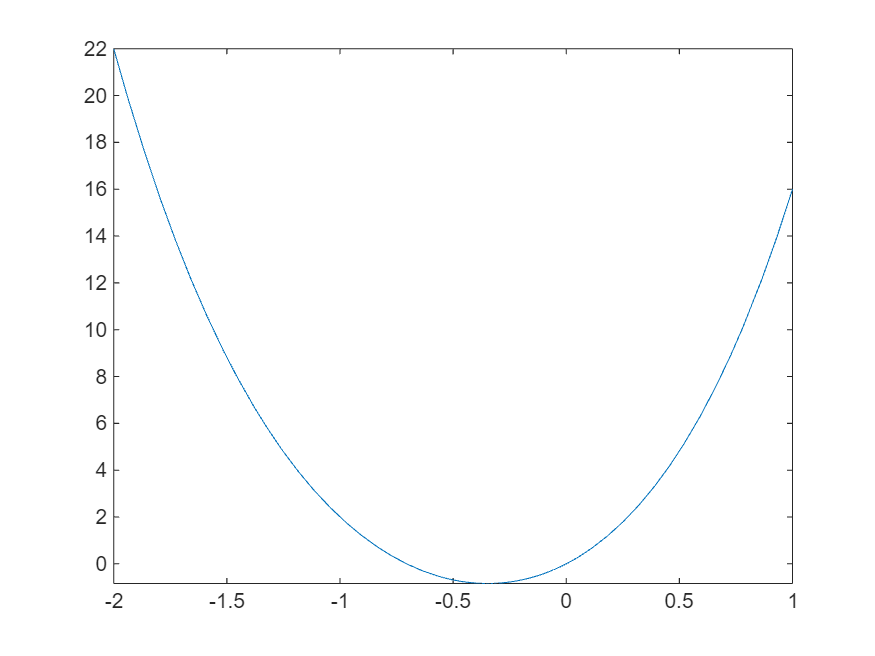

options = struct with fields:
                   Display: []
               MaxFunEvals: []
                   MaxIter: []
                    TolFun: []
                      TolX: 1.000000000000000e-06
               FunValCheck: []
                 OutputFcn: []
                  PlotFcns: []
           ActiveConstrTol: []
                 Algorithm: []
    AlwaysHonorConstraints: []
           DerivativeCheck: []
               Diagnostics: []
             DiffMaxChange: []
             DiffMinChange: []
            FinDiffRelStep: []
               FinDiffType: []
         GoalsExactAchieve: []
                GradConstr: []
                   GradObj: []
                   HessFcn: []
                   Hessian: []
                  HessMult: []
               HessPattern: []
                HessUpdate: []
          InitBarrierParam: []
     InitTrustRegionRadius: []
                  Jacobian: []
                 JacobMult: []
              JacobPattern: []
                Large

x =   -0.347250446101708


fval =   -0.840793935278626


exitflag =      1


output = struct with fields:
    iterations: 9
     funcCount: 10
     algorithm: 'golden section search, parabolic interpolation'
       message: 'Optimization terminated:↵ the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-06 ↵'


function [x] = chebyshev(a,b,n)
x=[];
for i = 1:n
    x=[ (a+b)/2 + (b-a)/2*cos((2*i-1)*pi/(2*n)), x];
end 
end